% add the necessary files to the path (this should be all that is required)
addpath(genpath(pwd))
addpath(genpath(fullfile(fileparts(pwd),'data')))
addpath(genpath(fullfile(fileparts(pwd),'utils')))

# Prerequisites, do not ignore!

We have included a fork of [deeplab-pytorch](https://github.com/kazuto1011/deeplab-pytorch) within this repo.  It must still be installed and configured to run with MATLAB. 

We recommend against using a virtual enviroment because it can be more complex to make it compatible with MATLAB. However it is not impossible to tell MATLAB to use a specific environment, it is just more stable with the base Anaconda environment. Once everything is downloaded and installed the original authors of [deeplab-pytorch](https://github.com/kazuto1011/deeplab-pytorch) recommended using these commands in the Anaconda prompt:

We recommend just opening the file: `deeplab-pytorch-master/configs/conda_env.yaml `and manually installing the dependencies. 

You will also need to install `pydensecrf `which can be done from the Anaconda prompt with this command. 

You will then need to install the pretrained model weights, but are likely to have trouble using wget. So you may manually download the weights at the URLs indicated in the file `deeplab-pytorch-master/scripts/setup_caffemodels.sh` and place them where indicated. 

The bash script which downloads the weights can be run like this:

After placing the model weights in the right folders you will need to run convert.py on the coco dataset

Only now can you expect MATLAB to run this code, and that is IF you configured MATLAB to work with python correctly. See other tutorial xxx

# Analyzing image content with a resNet image segmentation and labeling network trained on the COCO-stuff data set

Site the paper, site coco-stuff, site the models

Up a the top you will find controls for the text which let you control font properties and text type. Next to that is the code section, you switch between code and text by clicking those controls or using the "alt-enter" shortcut. 

To insert math you click the "insert tab" and you find options for equations. You will also find the ability to insert image insertion, and table of contents. 

Images and figures are embedded in to this document. You don't have to do a thing. All plots, figures, and print-statements are embedded. It is for this reason that it is highly recommended to keep your code blocks short and use plenty of text above and below them to explain what is happening. Don't write a paper though. 1-5 sentences is almost always sufficient.

The code output is put on the side by default. This can be hard to read, it is recommended to use the "output inline" option which you find in the "view" tab. 

## Single image example

First we will provide an example of running the segmentation and labeling on a single image. This will help you to understand the flow and how data is stored. 

#### Output the segmentation maps

 % There is a test image already located in the fork of deeplab-pytorch
 % you need only to provide a path to the image, see the help for what parameters are available. These are as used in Rose et al. 
 
imagePath=".\image.jpg"
[maps,resNetParams]=getLabelMaps(imagePath)

maps.labelMapList has 10 slices on the third dimension. Each slice is one iteration from our modifications to the segmentation and labeling process. The original process assigned one label to each pixel. Here we simply repeat that process, but for each iteration we eliminate the most widely assigned labels. Thus, for most pixels it is

[cloud]=convertMaps2Wordcloud(maps,resNetParams)

[adjMat]=getLabelRelationships(cloud,maps)

imagePath=fullfile('.\deeplab-pytorch-master',resNetParams.imagePath)
[fig,axList]=visualizeSingleSemanticLabelCloud(imagePath,cloud.labelLayer,cloud.sortedClassNames,adjMat.labelLocMap,adjMat.labelNetworkRelEnt)

# Functions


% im2Plot=getIm(outStruct,fInfo,expDataLoc);
%                 [fig,axList]=visualizeSingleSemanticLabelCloud(im2Plot,outStruct.outStruct.labelLayer,outStruct.outStruct.sortedClassNames,outStruct.outStruct.labelLocMap,outStruct.outStruct.labelNetworkOverlap,fig,axList);
%                
%         [outStruct,fInfo]=read(protDS);
%         monkList=[monkList;outStruct.t_monkey];
%         truShufList=[truShufList;tOS{TSNdx}];
%         semanticSegmentWords(end+1).sortedLabels=outStruct.outStruct.sortedLabels;
%         semanticSegmentWords(end).sortedClassNames=outStruct.outStruct.sortedClassNames;
%         semanticSegmentWords(end).labelLayer=outStruct.outStruct.labelLayer;


imagePath = ".\image.jpg"

Device: CPU
Model: DeepLabV2_ResNet101_MSC


maps = struct with fields:
    labelMapList: [513×513×10 double]
     probMapList: [513×513×10×182 double]
       classList: [1×1 py.dict]


resNetParams = struct with fields:
      configPath: ".\configs\cocostuff164k.yaml"
       modelPath: ".\data\models\coco\deeplabv1_resnet101\caffemodel\deeplabv2_resnet101_msc-cocostuff164k-100000.pth"
       imagePath: ".\image.jpg"
            cuda: 0
             crf: 1
      sizeThresh: 0.1111
    maxIteration: 10


cloud = struct with fields:
             nLayers: 10
           segImSize: [513 513]
        sortedLabels: [25×1 double]
    sortedClassNames: {25×1 cell}
          labelLayer: [25×1 double]
             nLabels: 25


adjMat = struct with fields:
       labelNetworkOverlap: [25×25 double]
    labelNetworkOverlapDir: [25×25 double]
     labelNetworkJointProb: [25×25 double]
        labelNetworkRelEnt: [25×25 double]
               labelLocMap: [513×513 double]
               labelClusts: [25×1 double]
            labelCentroids: [25×2 double]


imagePath = ".\deeplab-pytorch-master\image.jpg"

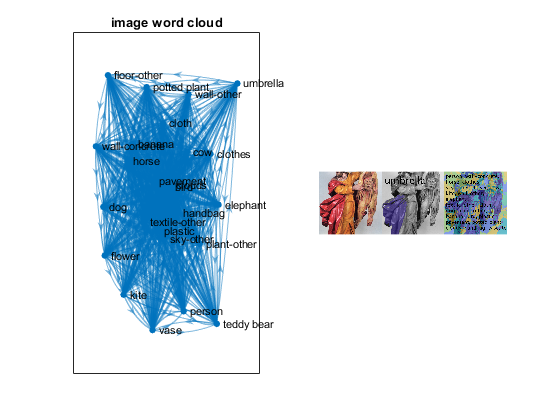

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


axList = 1×2 cell array
    {1×1 Axes}    {1×1 Axes}


function [maps,resNetParams]=getLabelMaps(imagePath,resNetParams)

if nargin<2 || ~isstruct(resNetParams)
configPath=".\configs\cocostuff164k.yaml";
modelPath=".\data\models\coco\deeplabv1_resnet101\caffemodel\deeplabv2_resnet101_msc-cocostuff164k-100000.pth";

resNetParams=struct('configPath',configPath,'modelPath',modelPath,'imagePath',imagePath,'cuda',false,'crf',true,'sizeThresh',1/9,'maxIteration',10);
end
doPlot=false;

try
    originalDir=pwd;
    cd(".\deeplab-pytorch-master")
catch
    cd("..")
    cd("..")
    originalDir=pwd;
    cd(".\deeplab-pytorch-master")
end
[a]=py.singleHierarchy.singleHierarchy(resNetParams.configPath,resNetParams.modelPath,imagePath,resNetParams.cuda,resNetParams.crf,resNetParams.sizeThresh,resNetParams.maxIteration,doPlot);
imagePath='';
cd(originalDir)


a=cell(a);
maps.labelMapList=cellfun(@(x) double(x), cell(a{1}),'Uni',false); maps.labelMapList=cat(3,maps.labelMapList{:});
maps.probMapList=cellfun(@(x) double(x), cell(a{2}),'Uni',false);  maps.probMapList=permute(cat(4,maps.probMapList{:}),[2,3,4,1]);
maps.classList=a{3};

end


    
function [cloud]=convertMaps2Wordcloud(maps,resNetParams)

    % get a list of all the labels represeneted
    unqLabels=unique(maps.labelMapList(:));
    unqClassNames=cellfun( @(x) char(maps.classList{x}),num2cell(unqLabels),'Uni',false);
    maps.classList=[];
    labelEdges=(unqLabels(1:end-1)+unqLabels(2:end))/2; labelEdges=[unqLabels(1);labelEdges;unqLabels(end)];
    % step through the label maps
    cloud.nLayers=size(maps.labelMapList,3);
    cloud.segImSize=size(maps.labelMapList,[1,2]);
    cloud.sortedLabels=[];
    cloud.sortedClassNames={};
    cloud.labelLayer=[];
    unWrap=@(x) x(:);
    for layer=1:cloud.nLayers
        % keep the unique values which cover more than 1/9th of the image
        N=histcounts(unWrap(maps.labelMapList(:,:,layer)),labelEdges,'Normalization','probability');
        bigLabels=unqLabels(N>=resNetParams.sizeThresh);
        bigClassNames=unqClassNames(N>=resNetParams.sizeThresh);
        % sort them by size and keep track of what level they are in
        % append them to the previous level
        [~,sortNdcs]=sort(N(N>=resNetParams.sizeThresh),'descend');
        cloud.labelLayer=[cloud.labelLayer;layer*ones(size(bigLabels))];
        cloud.sortedLabels=[cloud.sortedLabels;bigLabels(sortNdcs)];
        cloud.sortedClassNames=[cloud.sortedClassNames;bigClassNames(sortNdcs)];
    end
    cloud.nLabels=numel(cloud.sortedLabels);
end


function [adjMat]=getLabelRelationships(cloud,maps)
    
    
    % make a blank adjacency matrix
    adjMat.labelNetworkOverlap=zeros(cloud.nLabels);
    adjMat.labelNetworkOverlapDir=zeros(cloud.nLabels);
    adjMat.labelNetworkJointProb=zeros(cloud.nLabels);
    adjMat.labelNetworkRelEnt=zeros(cloud.nLabels);
    % make a deep boolean matrix representing the locations of all the labels represented (in order of the list)
    labelLocs=false([size(maps.labelMapList,[1,2]),numel(cloud.sortedLabels)]);
    probMap=squeeze(maps.probMapList(:,:,1,:)); probMap=probMap./sum(probMap,[1,2]);
    adjMat.labelLocMap=zeros(size(maps.labelMapList,[1,2])); % the sums in this map are uniquely defined by a combination of other layers
    sumLabelCodes=ones(1,cloud.nLabels);
    for labelNdx=1:cloud.nLabels
        label=cloud.sortedLabels(labelNdx);
        labelLocs(:,:,labelNdx)=any(maps.labelMapList==label,3);
        adjMat.labelLocMap(labelLocs(:,:,labelNdx))=adjMat.labelLocMap(labelLocs(:,:,labelNdx))+sumLabelCodes(labelNdx);
        if labelNdx<cloud.nLabels
            sumLabelCodes(labelNdx+1)=sum(sumLabelCodes(1:labelNdx))+1;
        end
    end
    % step through the labels and make the strength of the connection equal to the overlap of sections
    % we could also use joint distribution metrics (KL-divergence, mutual information, etc)
    for rowNdx=1:cloud.nLabels
        for colNdx=1:cloud.nLabels
            if rowNdx==colNdx; continue; end
            if rowNdx>=colNdx
                adjMat.labelNetworkOverlap(rowNdx,colNdx)=sum(labelLocs(:,:,rowNdx) & labelLocs(:,:,colNdx) ,'all')./sum(labelLocs(:,:,rowNdx) | labelLocs(:,:,colNdx) ,'all');
                adjMat.labelNetworkOverlap(colNdx,rowNdx)=adjMat.labelNetworkOverlap(rowNdx,colNdx);
                adjMat.labelNetworkJointProb(rowNdx,colNdx)=sum(exp(log(probMap(:,:,rowNdx))+log(probMap(:,:,colNdx))),'all'); % prevents some round off errors
                adjMat.labelNetworkJointProb(colNdx,rowNdx)=adjMat.labelNetworkJointProb(rowNdx,colNdx);
            end
            adjMat.labelNetworkOverlapDir(rowNdx,colNdx)=sum(labelLocs(:,:,rowNdx) & labelLocs(:,:,colNdx) ,'all')./sum(labelLocs(:,:,rowNdx),'all');
            adjMat.labelNetworkRelEnt(rowNdx,colNdx)=sum(probMap(:,:,rowNdx).*(log(probMap(:,:,rowNdx))-log(probMap(:,:,colNdx))),'all');
        end
    end
    adjMat.labelNetworkOverlap(logical(eye(size(adjMat.labelNetworkOverlap))))=1;
    
    numClusts=min(2,sum(cloud.labelLayer==1));
    [adjMat.labelClusts]=cluster(linkage(squareform(1-adjMat.labelNetworkOverlap),'average'),'maxclust',numClusts);
    
    % visualize by tying each label to it's segment centroid (avoid collisions)
    % step through the labels and get their probability weighted locations
    [cols,rows]=meshgrid(1:cloud.segImSize(2),1:cloud.segImSize(1));
    adjMat.labelCentroids=zeros(cloud.nLabels,2);
    for labelNdx=1:cloud.nLabels
        label=cloud.sortedLabels(labelNdx);
        probMap=maps.probMapList(:,:,1,label+1);
        probMap=probMap(:)./sum(probMap(:));
        adjMat.labelCentroids(labelNdx,:)=round(sum([rows(:).*probMap,cols(:).*probMap],1));
    end
end



function [fig,axList]=visualizeSingleSemanticLabelCloud(imagePath,labelLayer,sortedClassNames,labelLocMap,labelNetworkAdj,fig,axList)

try
    assert(isvalid(fig))
catch
    fig=figure();
end
try
    assert(length(axList)==2)
    assert(isvalid(axList{1}))
    assert(isvalid(axList{2}))
catch
    figure(fig)
    axList={subplot(1,2,1),subplot(1,2,2)};
end

nLabels=length(labelLayer);
labelLocs=getLabelLocsFromMap(nLabels,labelLocMap);

unDir=all(labelNetworkAdj==labelNetworkAdj',"all");
if unDir
    graphObj=graph(labelNetworkAdj,sortedClassNames,'omitselfloops');
else
    graphObj=digraph(labelNetworkAdj,sortedClassNames,'omitselfloops');
end
labelNetworkAdj=(~eye(size(labelNetworkAdj))).*(labelNetworkAdj+labelNetworkAdj)/2 + eye(size(labelNetworkAdj))*max(labelNetworkAdj(:));
LWidths = 5*graphObj.Edges.Weight/max(graphObj.Edges.Weight);

figure(fig)
axes(axList{1})
p=plot(graphObj,'LineWidth',LWidths,'Layout','force','WeightEffect','inverse');
title('image word cloud')


axes(axList{2}) % plot the main clusters
numClusts=min(2,sum(labelLayer==1));
[splits]=cluster(linkage(squareform(max(labelNetworkAdj(:))-labelNetworkAdj),'average'),'maxclust',numClusts);
numClusts=numel(unique(splits));
if numClusts==1;
numClusts=min(2,sum(labelLayer==1))+1;
[splits]=cluster(linkage(squareform(max(labelNetworkAdj(:))-labelNetworkAdj),'average'),'maxclust',numClusts);
numClusts=numel(unique(splits));
end

if ~isnumeric(imagePath)
    originalImage=imresize(imread(imagePath),size(labelLocMap,[1,2]));
else
    originalImage=imresize(imagePath,size(labelLocMap,[1,2]));
end
grayVersion=repmat(rgb2gray(originalImage),[1,1,3]);
imSize=size(originalImage);
clustMasks=zeros([size(labelLocMap,[1,2]),numClusts]);
clustClouds=cell(1,numClusts);
clustIms=cell(1,numClusts);
for ndx=1:numClusts
    clustMasks(:,:,ndx)=sum(labelLocs(:,:,splits==ndx),3);
    clustClouds{ndx}=sortedClassNames(splits==ndx);
    heatMapOverlay=labeloverlay(grayVersion,clustMasks(:,:,ndx),'Colormap','parula');
    FontSize=round(40+40/length(clustClouds{ndx}));
    % make sure the text fits in the image
    fontWidth=FontSize/2;
    imWidth=ceil(imSize(2)/fontWidth);
    cloudString=strjoin(clustClouds{ndx},', ');
    if length(cloudString)>=imWidth;
        nParts=ceil(length(cloudString)/imWidth);
        newLineLocs=zeros(1,nParts);
        temp=strfind(cloudString,' ');
        if length(temp)<nParts; temp=[temp,length(cloudString)+1]; end
        for insertCnt=1:nParts
            if insertCnt==1
                newLineLocs(insertCnt)=temp(find(temp<((insertCnt-1)*(imWidth-1)+imWidth) & temp>((insertCnt-1)*(imWidth-1)+1),1,'last'));
            else
                newLineLocs(insertCnt)=temp(find(temp<(newLineLocs(insertCnt-1)+imWidth) & temp>newLineLocs(insertCnt-1),1,'last'));
            end
        end
        cloudString(newLineLocs)=newline;
    end
    clustIms{ndx}=insertText(heatMapOverlay,[0,0],cloudString,'BoxOpacity',0,'TextColor',[1,0.97,0.95],'FontSize',FontSize-2);
end
if numClusts<4
montage([originalImage,clustIms],'Size',[1,numClusts+1])
else
montage([originalImage,clustIms])
end
drawnow


end


function labelLocs2=getLabelLocsFromMap(nLabels,labelLocMap)


sumLabelCodes=ones(1,nLabels);
for labelNdx=1:nLabels
    if labelNdx<nLabels
        sumLabelCodes(labelNdx+1)=sum(sumLabelCodes(1:labelNdx))+1;
    end
end
factorList=cell(nLabels,1);
for labNdx=1:nLabels
    factorList{labNdx}=factor(sumLabelCodes(labNdx));
end


isOdd=mod(labelLocMap,2)==1;
labelLocMap2=labelLocMap;
labelLocMap2(isOdd)=max(1,labelLocMap2(isOdd)-1);
labelLocs2=(labelLocMap2==permute(sumLabelCodes,[1,3,2]));
labelLocs2(:,:,1)=labelLocs2(:,:,1)  |  isOdd ;
uniqueSums=unique(labelLocMap2(:));
uniqueSums=setdiff(uniqueSums,sumLabelCodes);
uniqueSums=sort(uniqueSums,'descend');

nSums=numel(uniqueSums);
sumComps=cell(1,nSums);
foundsums=[];
missingSums=uniqueSums;
for sumNdx=1:nSums
    if ~isempty(sumComps{sumNdx}); continue; end
    sumVal=uniqueSums(sumNdx);
    
    % see if the sum has only one component
    knownComponents=sumLabelCodes(sumLabelCodes==sumVal);
    if isempty(knownComponents)
        possibleComponents=sort(sumLabelCodes(sumLabelCodes>1 & sumLabelCodes<sumVal),'descend');
        if sum(possibleComponents)==sumVal % see if the sum is all possible components
            knownComponents=possibleComponents;
        else
            % test all possible combinations
            compRows=possibleComponents'; % the first combination is just the one possible component so the "component rows" is width==1
            sumTest=sum(compRows,2);
            cnt=0;
            while ~any(sumTest==sumVal)
                cnt=cnt+1;
                % make a matrix of the sum of prior combinations  with another set of possible components
                [rows,cols]=meshgrid(1:size(compRows,1),possibleComponents);
                sumTest=possibleComponents'+sumTest'; % here is the matrix
                indexer=sumTest<=sumVal; % get rid of values larger than the sum
                sumTest=sumTest(indexer);
                compRows=sort([compRows(rows(indexer),:),cols(indexer)],2); % list the expanded set of combinations we just tested
                [compRows,indexer]=unique(compRows,'rows'); % the order of components doesn't matter so keep unique rows
                indexer=indexer(~any(diff(compRows,[],2)==0,2)); % no component can be repeated 2 or more times so get rid of repeats
                sumTest=sumTest(indexer);
                compRows=compRows(~any(diff(compRows,[],2)==0,2),:);
                % we might not have found the combination for the sum we are checking but we might have stumbled across another
                checkSums=sumTest==missingSums';
                if any(checkSums,'all')
                    foundSumNdcs=setdiff(find(any(checkSums,1)),foundsums);
                    foundsums=unique([foundSumNdcs,foundsums]);
                    missingSums(foundsums)=0;
                    % disp(['found ',num2str(length(foundSumNdcs)),' other sums'])
                    for foundSumNdx=foundSumNdcs
                        if ~isempty(sumComps{foundSumNdx}); continue; end
                        sumComps{foundSumNdx}=compRows(sum(compRows,2)==uniqueSums(foundSumNdx),:);
                        if size(sumComps{foundSumNdx},1)~=1; error('the labelLocMap is inconsistent with the number of labels'); end
                    end
                end
            end
            knownComponents=compRows(sum(compRows,2)==sumVal,:);
            if size(knownComponents,1)~=1; error('the labelLocMap is inconsistent with the number of labels'); end
        end
    end
    sumComps{sumNdx}=knownComponents;
end

for sumNdx=1:nSums
    knownComponents=sumComps{sumNdx};
    sumVal=uniqueSums(sumNdx);
    labelLocs2(:,:,ismember(sumLabelCodes,knownComponents))=labelLocs2(:,:,ismember(sumLabelCodes,knownComponents)) | labelLocMap2==sumVal;
end

end












